# RefMap quasi-loudness transform development

This script calculates the Sottek Hearing Model loudness values associated with the 2023 ISO 226 equal-loudness contours, then examines and optimises an adaptation of the Zwicker loudness transform function to match more closely with the apparent transform obtained with Sottek loudness.

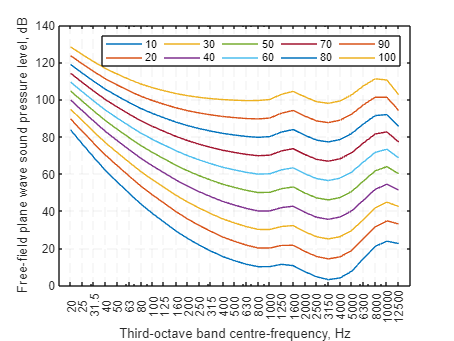

% Generate the ISO 226:2023 sound pressure values corresponding with each
% phon level and third-octave band centre-frequency

% ISO 532-1 Table A.6: critical band levels at threshold in quiet
levelThresQ = [30, 18, 12, 8, 7, 6, 5, 4,...
               3, 3, 3, 3, 3, 3, 3, 3, 3, 3, 3, 3];

% third-octave band frequencies
[fm, f1, f2, fn] = noctf([20, 12500], 3);

% ISO 226 equal loudness curve parameters
alphaf = [0.635, 0.602, 0.569, 0.537, 0.509, 0.482, 0.456, 0.433, 0.412, 0.391,...
          0.373, 0.357, 0.343, 0.330, 0.320, 0.311, 0.303, 0.300, 0.295,...
          0.292, 0.290, 0.290, 0.289, 0.289, 0.289, 0.293, 0.303, 0.323, 0.354];

luf = [-31.5, -27.2, -23.1, -19.3, -16.1, -13.1, -10.4, -8.20, -6.30, -4.60,...
       -3.20, -2.10, -1.20, -0.50, 0.000, 0.400, 0.500, 0.000, -2.70, -4.20,...
       -1.20, 1.400, 2.300, 1.000, -2.30, -7.20, -11.2, -10.9, -3.50];

threshf = [78.1, 68.7, 59.5, 51.1, 44.0, 37.5, 31.5, 26.5, 22.1, 17.9, 14.4,...
           11.4, 8.60, 6.20, 4.40, 3.00, 2.20, 2.40, 3.50, 1.70, -1.3, -4.2,...
           -6.0, -5.4, -1.5, 6.00, 12.6, 13.9, 12.3];

phonRange = [10; 20; 30; 40; 50; 60; 70; 80; 90; 100];

phon2spl = 10./alphaf.*log10((4*10^-10).^(0.3 - alphaf).*(10.^(0.03*repmat(phonRange, 1, length(fm))) - 10^0.072)...
           + (10.^(alphaf.*(threshf + luf)/10))) - luf;

spl2rms = 2e-5*10.^(phon2spl/20);

fig = figure;
semilogx(fm, phon2spl);
grid('on')
set(gca, 'XTick', fn, 'XTickLabel', fn, 'XLim', [16, 16e3], 'XMinorTick', 'off', 'GridAlpha', 0.05',...
    'GridLineStyle', '--', 'XMinorGrid', 'off')
xlabel("Third-octave band centre-frequency, Hz")
ylabel("Free-field plane wave sound pressure level, dB")
legend(string(phonRange), 'NumColumns', floor(length(phonRange)/2))

% generate a 5-s sinusoid corresponding with each sound pressure level in the
% spl2rms array, and calculate its loudness, without any outer-middle ear
% filtering
fs = 48e3;
t = linspace(0, 5 - 1/fs, 5*fs);
rms2sone = zeros(size(spl2rms));
iiS = size(spl2rms, 1);
jjS = size(spl2rms, 2);
parfor ii = 1:iiS
    for jj = 1:jjS
        signal = sqrt(2)*spl2rms(ii, jj).*sin(2*pi*fn(jj)*t);
        loudnessSHM = acousticSHMLoudness(signal, fs, 2, 'noEar', false, false, false);
        rms2sone(ii, jj) = loudnessSHM.loudnessPowAvg;
    end
end

% reduce array to critical band 'centres'
rms2soneCB = [rms2sone(:, 4), rms2sone(:, 9), rms2sone(:, 12:end)];
fnCB = [fn(4), fn(9), fn(12:end)];
phon2splCB = [phon2spl(:, 4), phon2spl(:, 9), phon2spl(:, 12:end)];

% generate a higher resolution for 1 kHz sinusoid

phonRange1k = [2.2; 4; 5; 7.5; 10; 15; 20; 25; 30; 35; 40; 45; 50; 55; 60; 65; 70; 75; 80; 85;...
               90; 95; 100; 105; 110; 115; 120];

spl2rms1k = 2e-5*10.^(phonRange1k/20);

rms2sone1k = zeros([length(spl2rms1k), 1]);
parfor ii = 1:length(phonRange1k)
    signal = sqrt(2)*spl2rms1k(ii).*sin(2*pi*1000*t);
    loudnessSHM = acousticSHMLoudness(signal, fs, 2, 'noEar', false, false, false);
    rms2sone1k(ii) = loudnessSHM.loudnessPowAvg;
end

% optimisation of 1k function
x01k = [0.103589607, 1.5016, 0.2552, 0.20627, -0.01067, 108.66, -17.03];
lb1k = [0.1, 1, 0.1, 0.1, -0.05, -1e5, -1e5];
ub1k = [0.11, 2, 0.4, 0.4, 0.025, 1e5, 1e5];

soneTarget1k = rms2sone1k;

optimFunc = @(q, X) loudnessTransform(X(:,1), X(:,2), q);

options = optimoptions('lsqcurvefit', 'MaxFunctionEvaluations', 1e4, 'Algorithm', 'interior-point');

[q_opt1k, resnorm, residual, exitflag, output] = ...
    lsqcurvefit(optimFunc, x01k, [phonRange1k, repmat(levelThresQ(fnCB == 1000), size(phonRange1k, 1), 1)],...
                rms2sone1k, lb1k, ub1k, options);


Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% optimisation of other critical bands
q_optCB = zeros([length(q_opt1k), length(fnCB)]);
q_optCB(:, fnCB == 1000) = q_opt1k;

% initial parameter values
x0 = [0.042073189, -14.59857478, 0.103699189, 0.174001493, -0.03136299, 92.57369062, -28.78359333;
      0.040135337, -2.181006406, 0.108673519, 0.211990218, -0.009312837, 94.07961678, -19.0019942;
      0.055940743, 1.0, 0.4, 0.219924308, -0.01664898, 116.605044, -42.32829989;
      0.073176551, 0.5, 0.5, 0.202536774, -0.007097562, 89.5721625, -15.78716594;
      0.092115643, 1.149999999, 0.300000001, 0.196182779, -0.008927165, 90.24311787, -19.74458355;
      0.117916508, 1.149994005, 0.300009837, 0.187107973, -0.012015454, 88.1214034, -25.60404339;
      0.131306241, 1.19558383, 0.285915631, 0.186968293, -0.013872571, 90.16238218, -26.99737673;
      0.13941632, 1.201079272, 0.281264203, 0.18729956, -0.013560672, 91.81793046, -28.03120856;
      0.109431468, 1.159297862, 0.215960816, 0.210022629, -0.02138309, 118.9890784, -33.85091717;
      0.098905011, 0.463610787, 0.513888118, 0.194700276, -0.007953587, 99.2068481, -20.35050499;
      0.098160845, 0.763271806, 0.2, 0.198741374, -0.008868945, 101.0557993, -19.86652011;
      0.134433918, 0.778497926, 0.217416627, 0.192094268, -0.013627156, 104.9736866, -24.28401097;
      0.161114596, 1.27457493, 0.224108881, 0.187608559, -0.014572434, 102.7916212, -22.83179388;
      0.190709762, 15.8613793, 0.407493697, 0.198915826, -0.035147152, 115.5363546, -34.60952449;
      0.203884327, 2.080100574, 0.258795871, 0.190210851, -0.026977291, 109.6445913, -26.74024968;
      0.162669515, 1.077675378, 0.30474587, 0.184465972, -0.01410319, 102.5550921, -17.92639656;
      0.101922697, 1.077587567, 0.800001768, 0.193197089, -0.014393432, 112.1938718, -17.71426601;
      0.06825211, 0.09998681, 0.299722389, 0.221826309, -0.036569288, 128.2714066, -17.15079401;
      0.063823175, 0.099949504, 0.300558383, 0.217674237, -0.034408342, 125.9039073, -16.328818;
      0.06105491, 0.099802978, 0.303714288, 0.21129216, -0.030913821, 108.8187685, -4.568509235].';

% parameter bounds
lb = [0.01, -4, 0.1, 0.1, -1e-1, 0.1, -100].';
ub = [0.25, 30, 1.0, 0.4, -1e-6, 200, -0.1].';

% optimisation loop over critical bands
for ii = length(fnCB):-1:1

    if fnCB(ii) == 1000
        continue
    else
        soneTarget = rms2soneCB(:, ii);

        [q_opt, resnorm, residual, exitflag, output] = ...
            lsqcurvefit(optimFunc, x0(:, ii), [phon2splCB(:, ii), repmat(levelThresQ(ii), length(phon2splCB(:, ii)), 1)],...
                        soneTarget, lb, ub, options);

        resnormCB(ii) = resnorm
        q_optCB(:, ii) = q_opt
    end
end


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000640762488380   0.000522723943481   0.001350095066564   0.002090449378552   0.012477392190964   0.002430717567888   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000640762488380   0.000522723943481   0.001350095066564   0.002090449378552   0.012477392190964   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000640762488380   0.000522723943481   0.001350095066564   0.002090449378552   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0                   0                   0                   0                   0   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0                   0                   0                   0                   0   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000640762488380   0.000522723943481   0.001350095066564   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0                   0                   0                   0   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0                   0                   0                   0  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000640762488380   0.000522723943481   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0                   0                   0   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0                   0                   0   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000640762488380   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0                   0   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0                   0   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024192871   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0                   0   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0                   0   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000382935252174   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0                   0   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0                   0   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689123434801   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0                   0   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0                   0   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001225413274996   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575                   0   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309                   0   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911640074191                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0                   0   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0                   0   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0                   0   0.002160316152


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663287397028   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0                   0   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0                   0   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0                   0   0.006054088176115   0.002160316152


Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791754565008   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0                   0   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0                   0   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0                   0   0.003747573236684   0.006054088176115   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001184364570380   0.000791635954972   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0                   0   0.001385479040638   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0                   0   0.144981572709487   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0                   0   0.004569544280028   0.003747573236684   0.006054088176115   0.002160316152


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.005455465127023   0.001181515189517   0.000791635954972   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0                   0   0.001443383870381   0.001385479040638   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0                   0   0.269618721060537   0.144981572709487   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0                   0   0.004778566257311   0.004569544280028   0.003747573236684   0.006054088176115   0.002160316152


Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001539246747511   0.017139103121329   0.001181515189517   0.000791635954972   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0                   0   0.001327699902629   0.001443383870381   0.001385479040638   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0                   0   0.140747011015335   0.269618721060537   0.144981572709487   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0                   0   0.005501891140196   0.004778566257311   0.004569544280028   0.003747573236684   0.006054088176115   0.002160316152


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444606491   0.001537948725093   0.017139103121329   0.001181515189517   0.000791635954972   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0                   0   0.002496524685855   0.001327699902629   0.001443383870381   0.001385479040638   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0                   0   0.275041570037957   0.140747011015335   0.269618721060537   0.144981572709487   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0                   0   0.003461227127974   0.005501891140196   0.004778566257311   0.004569544280028   0.003747573236684   0.006054088176115   0.002160316152


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037818615769350   0.002860444782554   0.001537948725093   0.017139103121329   0.001181515189517   0.000791635954972   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

                   0   0.002448930666980   0.002496524685855   0.001327699902629   0.001443383870381   0.001385479040638   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
                   0   0.001896894800145   0.275041570037957   0.140747011015335   0.269618721060537   0.144981572709487   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
                   0   0.001000807572654   0.003461227127974   0.005501891140196   0.004778566257311   0.004569544280028   0.003747573236684   0.006054088176115   0.002160316152


Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


resnormCB =    0.037816040726336   0.002860444782554   0.001537948725093   0.017139103121329   0.001181515189517   0.000791635954972   0.000663307912386   0.000911156046696                   0   0.001224376928423   0.000689304921384   0.000380097769731   0.000163024239784   0.000172422011217   0.000522446074888   0.001350013070745   0.002166637846670   0.006709685289642   0.009256063036318   0.007909022301962


q_optCB = 1.0e+02 *

   0.000216211014620   0.002448930666980   0.002496524685855   0.001327699902629   0.001443383870381   0.001385479040638   0.001278517208902   0.001229884463483   0.001094322624575   0.001401109701987   0.001275325315036   0.001288249532329   0.001254233267640   0.001137139745865   0.001142210221268   0.001156741030670   0.001170452173171   0.001236140837582   0.001282925340219   0.001293880813562
   0.129997784114591   0.001896894800145   0.275041570037957   0.140747011015335   0.269618721060537   0.144981572709487   0.039607614730472   0.250327217497616   0.011637566607309   0.217640099113582   0.157816186599824   0.016268026442979   0.021156429602902   0.197133969292022   0.122975292033567   0.149609171919786  -0.023251065658518   0.104449368579285   0.115131700928274   0.109776844794432
   0.005500046504155   0.001000807572654   0.003461227127974   0.005501891140196   0.004778566257311   0.004569544280028   0.003747573236684   0.006054088176115   0.002160316152

Functions

function sone = loudnessTransform(splCB, ltqCB, q)
    q1 = q(1);
    q2 = q(2);
    q3 = q(3);
    q4 = q(4);
    q5 = q(5);
    q6 = q(6);
    q7 = q(7);
    
    q0 = q2.*exp(-q3.*splCB) + q4 + q5.*tanh((splCB - q6)/q7);
    sone = q1*(10.^(0.1*ltqCB)).^q0.*((1 - 0.25 + 0.25.*(10.^((splCB - ltqCB)./10))).^q0 - 1);
    sone = sone.*exp(0.98454256);

end
